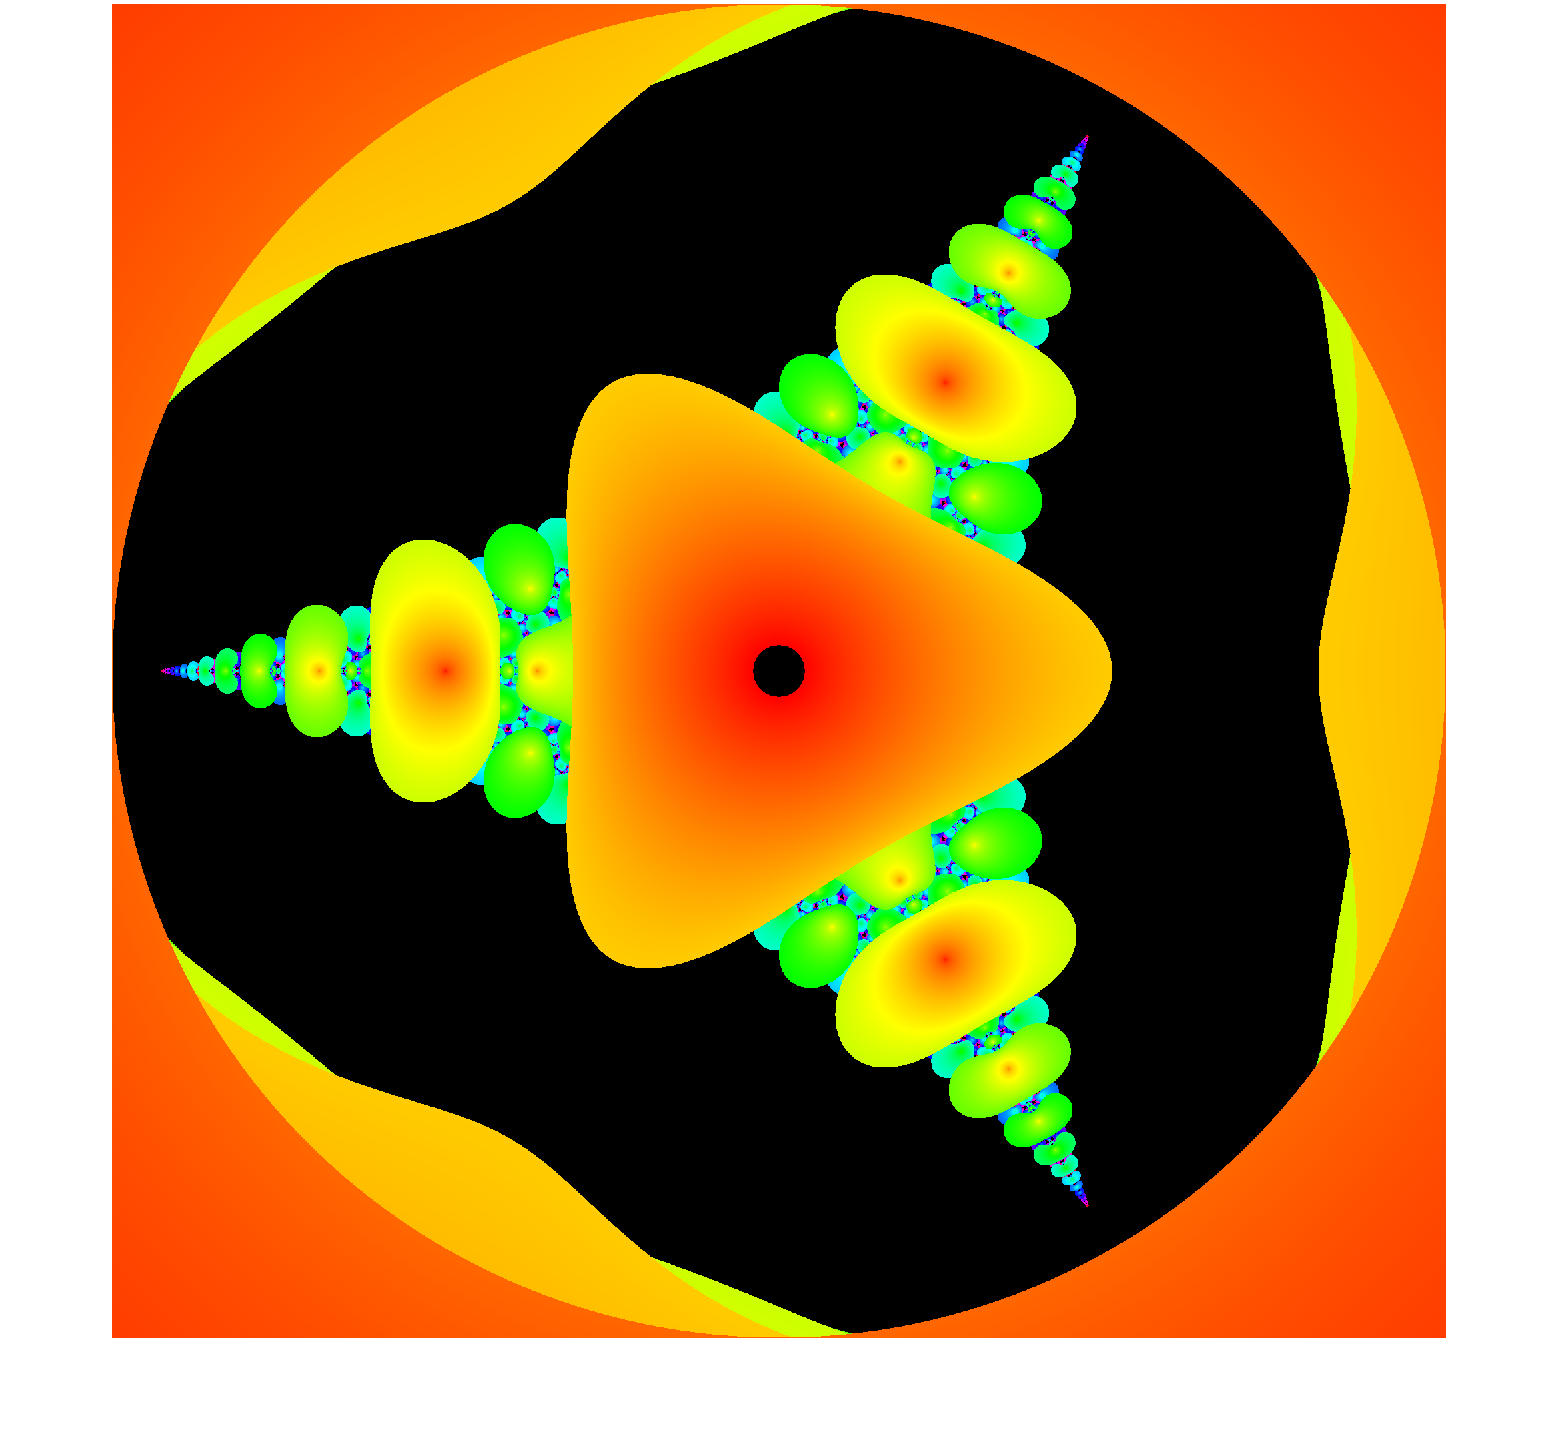

%simple(15, 2000)
%colored(15, 2000)
bettercolored(15, 2000)

function output = bettercolored(max_iter, res)
    x = linspace(-2, 2, res);
    y = linspace(-2, 2, res);
    hsv_image = [];
    
    for j = 1:res
        for k = 1:res
            c = x(j) + y(k)*1i;
            z = c;
            n = 0;
            while abs(z) < 2 && n < max_iter
                z = z^-2 + c;
                n = n + 1;
            end
            if n < max_iter
                n = n + 1 - log(log2(abs(z)));
                hsv_image(k, j, 3) = 1;
            else
                n = max_iter;
                hsv_image(k, j, 3) = 0;
            end
            hsv_image(k, j, 1) = n / max_iter;
            hsv_image(k, j, 2) = 1;
        end
    end
    rgb_image = hsv2rgb(hsv_image);
    imshow(rgb_image)
end

function output = colored(max_iter, res)
    x = linspace(-2, 2, res);
    y = linspace(-2, 2, res);
    image_matrix = [];
    
    for j = 1:res
        for k = 1:res
            c = x(j) + y(k)*1i;
            z = c;
            n = 0;
            while abs(z) < 2 && n < max_iter
                z = z^-2 + c;
                n = n + 1;
            end
            if n < max_iter
                n = n + 1 - log(log2(abs(z)));
            end
            image_matrix(k, j) = 255 * (n / max_iter);
        end
    end
    image(image_matrix)
end

function output = simple(depth, res)
    x = linspace(-2, 2, floor(res * 0.75));
    y = linspace(-2, 2, res);
    x_axis = [];
    y_axis = [];
    
    for j = 1:floor(res * 0.75)
        for k = 1:res
            c = x(j) + y(k)*1i;
            z = c;
            for l = 1:depth
                z = z^-2 + c;
                if abs(z) > 2
                    break
                end
            end
            if abs(z) < 2
                x_axis = [x_axis x(j)];
                y_axis = [y_axis y(k)];
            end
        end
    end
    scatter(x_axis, y_axis, 1, 'filled')
end